# Laboratorio 2 de Febrero del 2023, Análisis Aplicado, ITAM

## Problema de Fermat-Weber

clear; clc; close all;

load Puntos.mat
A

A =     1.1440   -4.1062    4.2911   11.3544   -3.0526    0.3560    8.2198    0.5753    1.1728    1.5659   -0.5260   -6.0499   -9.7679    1.3917    4.1329
   -1.8071   -1.6202   -4.6155   -1.1673   -4.2520    5.7343   -3.6919   -3.2334    0.5163   -5.6399   -1.9160   -3.3424   -1.5992   -0.2265    3.1824
    0.6039    2.6745    5.2061   -3.3578    0.3233   10.5999   11.0062    2.9804    1.9679   -0.9725    6.0581   -4.9188   -2.2799   -0.9680   -0.5919


[n,m] = size(A);
vc = zeros(3,1);

for j = 1:m
    v = A(:,j); vc = vc + v;
    plot3(v(1), v(2), v(3), 'dr', 'LineWidth', 3);
    hold on
end

vc = vc/m;

plot3(vc(1), vc(2), vc(3), 'sk', 'LineWidth', 3);
hold on
title('Problema de Fermat-Weber')

fname = 'ferweb'; x0 = 20 * randn(3,1);


Código de máximo descenso

[xf1, j1] = desmax(fname, x0);

Código de Newton

[xf2, j2] = desnewton(fname, x0);

 1 4899306.53331605 
  2 2738163.17847953 
  3 1952434.36042612 
  4 5024558.12706800 
  5 5143849.58233933 
  6 4828067.20414760 
  7 5058681.63165857 
  8 3893640.40185960 
  9 3075653.19029572 
 10 4516343.54144128 
 11 2259257.43528997 
 12 5084197.64651781 
 13 5062087.25738265 
 14 5171249.12560410 
 15 5171302.39278480 
 


sol = [xf1 xf2 vc]

sol =     4.1329  150.4663    0.7134
    3.1824   65.2040   -1.5786
   -0.5919   22.8112    1.8888



iter = [j1 j2]

iter =    100    15


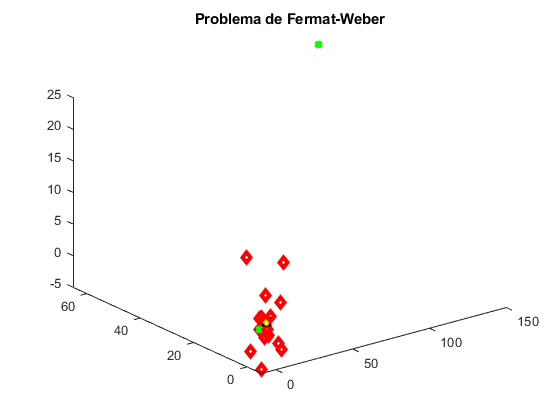



plot3(xf1(1), xf1(2), xf1(3), 'xg', 'LineWidth', 3);
hold on

plot3(xf2(1), xf2(2), xf2(3), 'xg', 'LineWidth', 3);
hold on

plot3(vc(1), vc(2), vc(3), '+y', 'LineWidth', 3);
hold on


fopt = feval(fname, xf1);
fvc = feval(fname, vc);
vf = [fopt fvc]

vf = 	1.0e+07 *

    1.4779    3.1688



g = gradiente(fname, xf1);
ng = norm(g)

ng = 1.2320e+05